# Sample 11-1

## 画像ノイズ除去

加法性白色ガウスノイズ

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Additive whitel Gaussian noise

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## 画像生成

(Image generation)

-         $\mathbf{u}\in\mathbb{R}^N$: 原画像 (Original image)

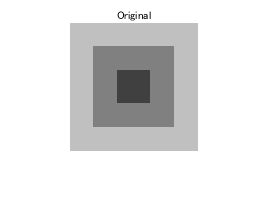

% Original image u
u = 0.75*ones(128);
u(24:128-24,24:128-24) = 0.5;
u(48:128-48,48:128-48) = 0.25;

figure(1)
imshow(u)
title('Original')

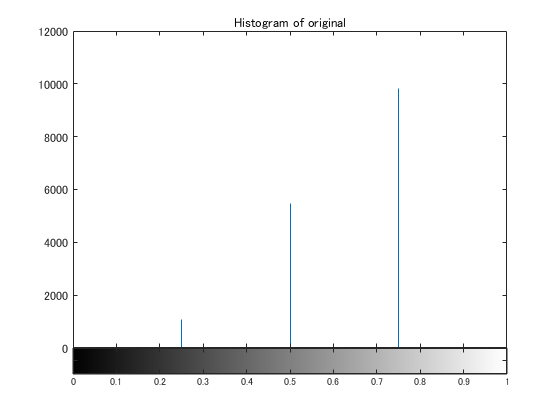

figure(2)
imhist(u)
title('Histogram of original')
set(gca,'YLim',[0 12000])

### 白色ガウスノイズ

(White Gaussian noise)

ノイズはガウス分布(正規分布)に従う乱数と仮定．(Noise is assumed to be a random number drawn from a Gaussian distribution (normal distribution).)

- $\mathbf{w}\sim\mathrm{Norm}(\mathbf{w}|\mathbf{\mu}_w,\mathbf{\Sigma}_w)$: ノイズ (Noise)

- 
$$\mathrm{Norm}(\mathbf{x}|\mathbf{\mu},\mathbf{\Sigma})=\frac{1}{\sqrt{2 \pi |\mathbf{\Sigma}|}} \exp \left(-\frac{1}{2 }(\mathbf{x}-\mathbf{\mu})^T\mathbf{\Sigma}^{-1}(\mathbf{x}-\mathbf{\mu})\right), \quad \mathbf{x} \in \mathbb{R}^{N}$$


白色とは零平均 (zero mean) かつ 独立同一分布 i.i.d. (independently and identical distribution)を意味する．(White means zero mean and i.i.d. (independent and identical distribution)).

- 
$$\mathbf{\mu}_w=\mathbf{0}$$


- 
$$\mathbf{\Sigma}_w = \sigma_w^2\mathbf{I}$$


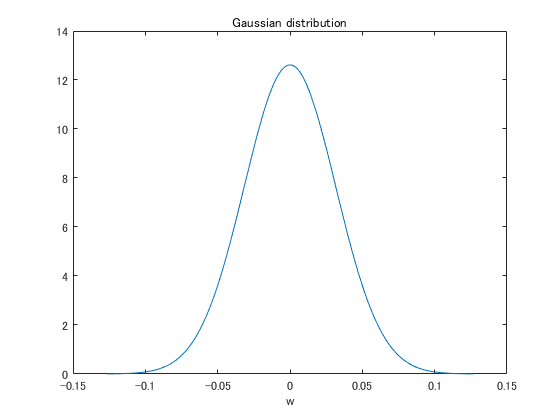

% Gaussain parameters
muw = 0;
sgmw2 = 0.001;
sgmw  = sqrt(sgmw2);

% Gaussian distribution
x = linspace(-4*sgmw,4*sgmw,1000);
wpdf = normpdf(x,muw,sgmw);
figure(3)
h = plot(x,wpdf);
xlabel('w')
title('Gaussian distribution') 

擬似乱数生成 (Pseudo-random number generation)

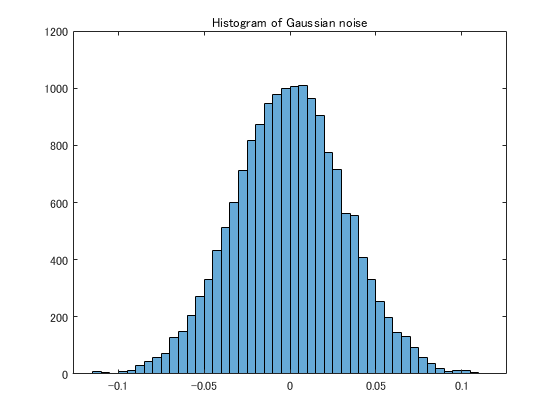

% Additive white Gaussian noise
w = sqrt(sgmw2)*randn(size(u));
figure(4)
histogram(w(:))
title('Histogram of Gaussian noise')
set(gca,'XLim',[-4*sgmw 4*sgmw])

### 観測画像

(Observed image)

加法性白色ガウスノイズによる劣化のシミュレーション (Simulation of degradation by additive White Gaussian noise)

- $\mathbf{v}=\mathbf{u}+\mathbf{w}\in\mathbb{R}^N$: 観測画像 (Observed image)

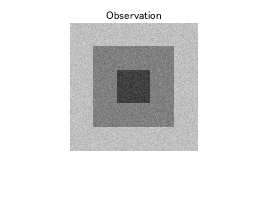

% Noisy observation
v = u + w;
figure(5)
imshow(v)
title('Observation')

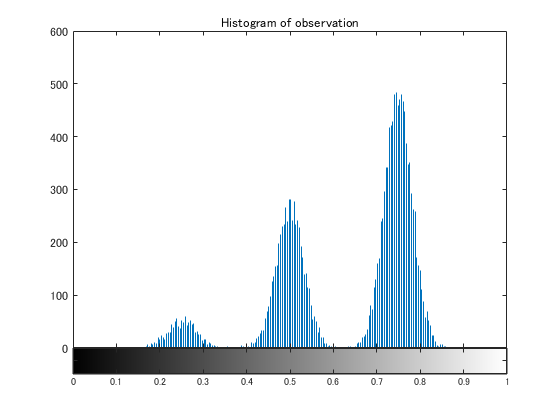

figure(6)
imhist(v)
title('Histogram of observation')
set(gca,'YLim',[0 600])

### ノイズ画像生成

(Generation of noisy image)

IMNOISE関数を利用できる．(IMNOISE function can be used.)

加法性白色ガウスノイズ(AWGN)を与える例．(Example of giving additive white Gaussian noise(AWGN).)

msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


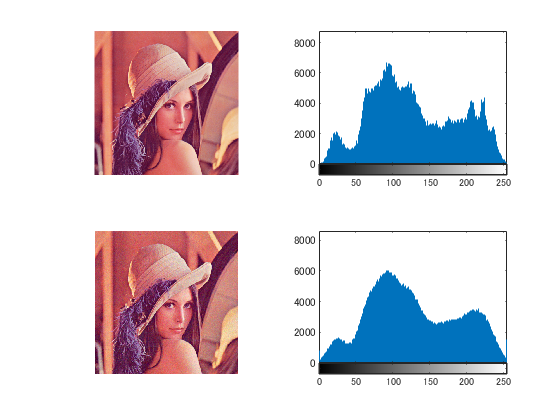

I = imread('./data/lena.png');
J = imnoise(I,'gaussian',muw,sgm2);
figure(7)
subplot(2,2,1)
imshow(I)
subplot(2,2,2)
imhist(I)
subplot(2,2,3)
imshow(J)
subplot(2,2,4)
imhist(J)

© Copyright, Shogo MURAMATSU, All rights reserved.